Wrocław 14.04.2021

Aleksander Kudyba

245084

# Ruchliwość i rezystywność w domieszkowanych półperzewdnikach

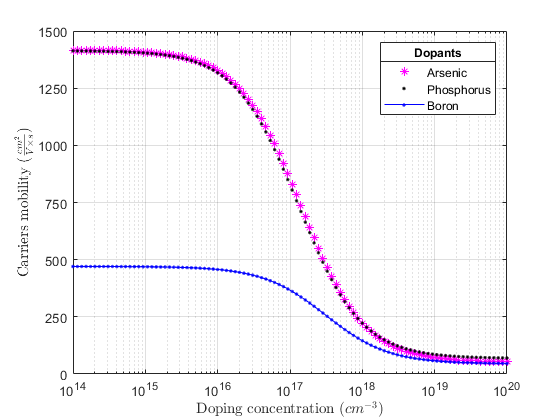

Nd = logspace(14,20,100);
syms x;
% 1- Arsenic (n-type), 2- Phosphorus (n-type), 3- Boron (p-type), mu (cm^2/V/s), N (cm^(-3))
q = 1.602e-19; % w coulombach
mu1_max = 1417; 
mu1_min = 52.2;
Nr1 = 9.68e16;
alpha1 = 0.68;
mu2_max = 1414;
mu2_min = 68.5;
Nr2 = 9.20e16;
alpha2 = 0.711;
mu3_max = 470.5;
mu3_min = 44.9;
Nr3 = 2.23e17;
alpha3 = 0.719;

mu1(x) = mu1_min + (mu1_max - mu1_min)/(1 + (x/Nr1)*alpha1);
mu1_fin = double(mu1(Nd));
rho1(x) = 1/(q*x*mu1(x));
rho1_fin = double(rho1(Nd));

mu2(x) = mu2_min + (mu2_max - mu2_min)/(1 + (x/Nr2)*alpha2);
mu2_fin = double(mu2(Nd));
rho2(x) = 1/(q*x*mu2(x));
rho2_fin = double(rho2(Nd));

mu3(x) = mu3_min + (mu3_max - mu3_min)/(1 + (x/Nr3)*alpha3);
mu3_fin = double(mu3(Nd));
rho3(x) = 1/(q*x*mu3(x));
rho3_fin = double(rho3(Nd));

semilogx(Nd, mu1_fin, '*m', Nd, mu2_fin, '.k', Nd, mu3_fin, '.-b', "LineWidth", 0.5)
lgd = legend('Arsenic', 'Phosphorus', 'Boron');
title(lgd, 'Dopants');
yticks(0:250:1500);
xlabel("Doping concentration $(cm^{-3})$",'Interpreter','latex');
ylabel("Carriers mobility ($\frac{cm^2}{V\times s}$)",'Interpreter','latex');

xlim('auto')
ylim('auto')
grid on

Ruchliwość maleje przy większej koncentracji domieszek, ze względu na rozpraszanie się na nich nośników. Wpływ rozpraszania na domieszkach maleje kiedy ich koncentracj jest na tyle duża, że już większośc atomów jest zjonizowana. Ze względu na typ domieszkowania mamy do czynienia z różnym typem nośników. Z tego też powodu ruchliwośc dla domieszkowania borem jest niższa, ponieważ zamiast dodatkowych elektronów powstają tu dziury i one są nośnikiem. Ich masa efektywna jest większa niż elektronów, a ruchliwość jest odwrotnie proporcjonalna do masy efektywnej nośników.

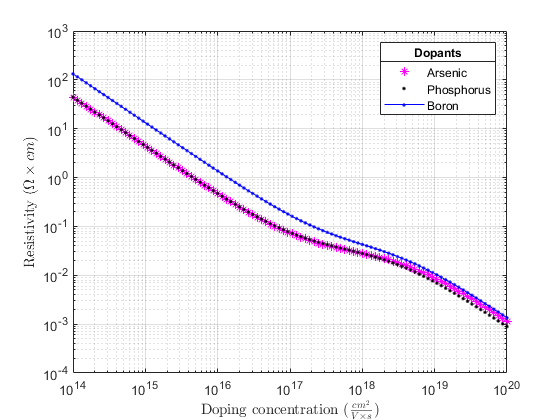

loglog(Nd, rho1_fin, '*m', Nd, rho2_fin, '.k', Nd, rho3_fin, '.-b', "LineWidth", 0.5)
lgd = legend('Arsenic', 'Phosphorus', 'Boron');
title(lgd, 'Dopants');
xlabel("Doping concentration ($\frac{cm^2}{V\times s}$)",'Interpreter','latex');
ylabel("Resistivity $(\Omega\times cm)$",'Interpreter','latex');

xlim('auto')
ylim('auto')
grid on

Tak też w przypadku rezystywności według zależności $\rho= \frac{1}{\sigma}=\frac{1}{q(n\mu_n + p\mu_p)}$, gdzie przyjmujemy zgodnie z typem domieszkowania $n$ lub $p$ równe zeru, bedzie ona większa dla domieszkowania borem.